# Next Paper, Journal?

### TO DO

- degradation parameter std should start off large and then update based on the true system filters

- parallelize digitaltwin execution, gather total flight times, create distribution. this is RUL for next true system flight

### Load paths and variables

addpath(genpath(pwd));
load_fresh_workspace;
load_trajectory;
%init_simulation_params;

### Simulate

Mode Selection 

- true system - nominal

- true system - degraded

- digital twin - nominal

- digital twin - degraded

sys = "TrueSystem";
%sys = "DigitalTwin";

mode = "Nominal";
%mode = "Degraded";

% degraded_level needs fixed to reflect the non-accelerated degradation
% profiles, before 11 was really degraded, now it is hardly
degraded_level = 11;

Degraded or Nominal

if mode == "Degraded"
    battery.R0=rdeg(degraded_level);
    battery.Q=qdeg(degraded_level);
    Motor2.Req=mdeg(degraded_level);
    Motor4.Req=mdeg(degraded_level);
else
    battery.R0=rdeg(1);
    battery.Q=qdeg(1);
    Motor2.Req=mdeg(1);
    Motor4.Req=mdeg(1);
end

if sys == 'TrueSystem'
    octomodel.sampletime = .025;
    disp('true system simulation');
    load_system('truesystem');
    tic
    sim('truesystem.slx');
    toc
else
    batterytwin = battery;
    Motortwin2 = Motor2;
    Motortwin4 = Motor4;
    octomodel.sampletime = .05;
    load_system('digitaltwin1c');
    tic
    sim('digitaltwin1c.slx');
    toc
end

true system simulation


Elapsed time is 229.979292 seconds.


rul = flight_time.Data(end)

rul = 19.4500

## Plot Path

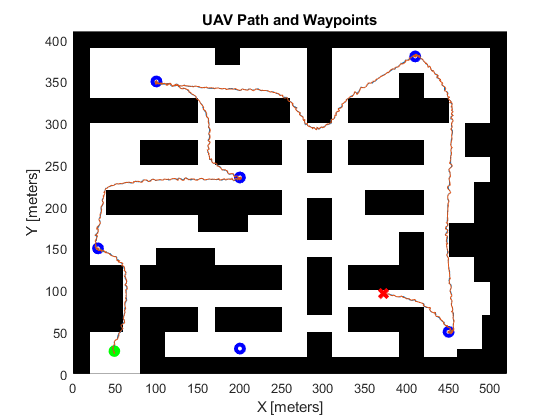

f1 = figure(1); clf;
hold on;
show(map);
plot(pos_observed.Data(1,1), pos_observed.Data(1,2), 'go', 'markerfacecolor', 'g', 'markersize', 8);
for i = 1:length(waypoints)
   plot(waypoints(i,1), waypoints(i,2), 'bo', 'LineWidth', 3); 
end
plot(pos_actual.Data(:,1), pos_actual.Data(:,2));
plot(pos_observed.Data(:,1), pos_observed.Data(:,2));
if ~any(stop_code.Data(:,3))
    plot(pos_observed.Data(end, 1), pos_observed.Data(end, 2), 'rx', 'markersize', 9, 'LineWidth', 3);
end
hold off;
title("UAV Path and Waypoints");

## Euclidean Position Error

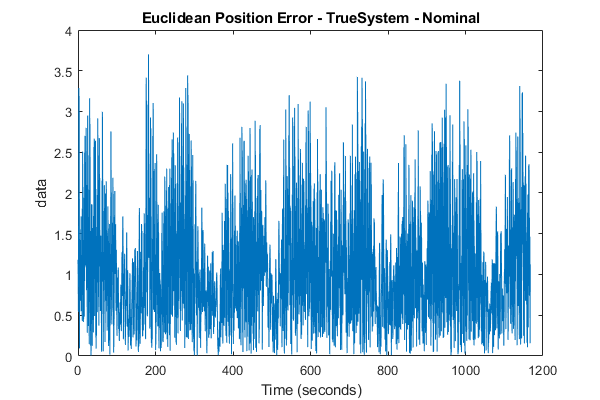

f2 = figure(2); clf;
plot(euclidean_pos_err);
ttl = sprintf("%s - %s - %s", 'Euclidean Position Error', sys, mode);
title(ttl);

## Voltage and SOC Plot

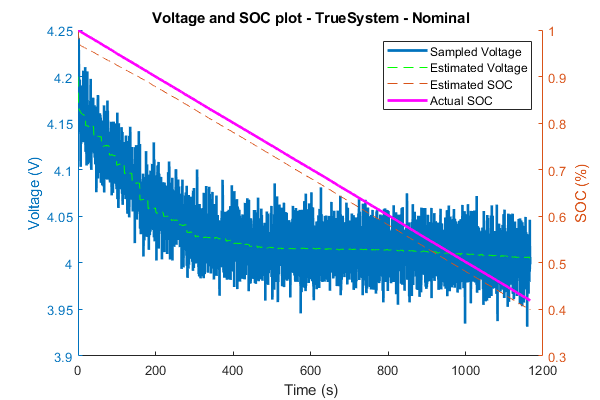

f2 = figure(2); clf;
f2.Position = [0 0 600 400];
yyaxis left;
hold on;
plot(battery_observed.Time(:), battery_observed.Data(:,1), 'linewidth', 2, "DisplayName", "Sampled Voltage");
plot(battery_actual.Time(:), battery_actual.Data(:,1), 'g', "DisplayName", "Estimated Voltage");
hold off;
ylabel("Voltage (V)");
yyaxis right;
hold on;
plot(battery_observed.Time(:), battery_observed.Data(:,2), '--', "DisplayName", "Estimated SOC");
plot(battery_actual.Time(:), battery_actual.Data(:,2),'m-', 'linewidth', 2, "DisplayName", "Actual SOC");
hold off;
ttl = sprintf("%s - %s - %s", 'Voltage and SOC plot', sys, mode);
title(ttl);
xlabel("Time (s)");
ylabel("SOC (%)");
legend();

## Current Plot

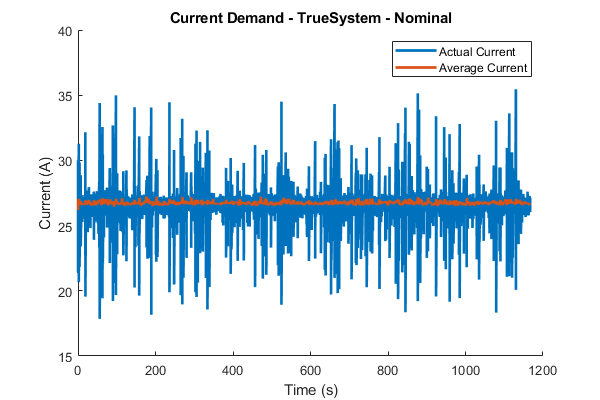

r0_var = 0.0022

Q_var = 0.9487

f2 = figure(2); clf;
f2.Position = [0 0 600 400];
hold on;
plot(current_actual.Time(:,1), current_actual.Data(:,1), 'linewidth', 2, "DisplayName", "Actual Current");
plot(downsample(current_actual.Time(:,1), 5),smoothdata(downsample(current_actual.Data(:,1), 5), 'rlowess', 20), 'linewidth', 2, "DisplayName", "Average Current");
ttl = sprintf("%s - %s - %s", 'Current Demand', sys, mode);
title(ttl);
xlabel("Time (s)");
ylabel("Current (A)");
ylim([15 40]);
legend();

# *********************************************************************************************************************

# Simulation Loop 

# *********************************************************************************************************************

- load main workspace 

addpath(genpath(pwd));
load_fresh_workspace;
load_trajectory;


- main loop

% counter for each true system simulation
true_ctr = 1;

% counter for combining parallel simulation results
idx_ctr = 1;
% loop 

octomodel.sampletime = true_sample_rate;
tic
sim('truesystem.slx');
toc

Elapsed time is 236.868693 seconds.


r_var = battery_observed.Data(end, 5)

r_var = 0.0022

q_var = battery_observed.Data(end, 7)

q_var = 0.9487

m_var = motors.Data(2, 4)

m_var = 0.0020

battery.R0 = normrnd(rdeg(true_ctr), r_var);
battery.Q = normrnd(qdeg(true_ctr), q_var);
Motor2.Req = normrnd(mdeg(true_ctr), m_var);

- define placeholder variables

twin_flight_times(true_ctr,:) = zeros(1,48);
twin_voltages(true_ctr,:) = zeros(1,48);
twin_socs(true_ctr,:) = zeros(1,48);
twin_r0s(true_ctr,:) = zeros(1,48);
twin_qs(true_ctr,:) = zeros(1,48);
twin_mot_res(true_ctr,:) = zeros(1,48);
twin_pos_errs(true_ctr,:) = zeros(1,48);

- now simulate digital twin 48 times (12 cores x 4 iterations)

octomodel.sampletime = twin_sample_rate;
numRuns = 12;

Starting parallel pool (parpool) using the 'local' profile ...
Preserving jobs with IDs: 1 because they contain crash dump files.
You can use 'delete(myCluster.Jobs)' to remove all jobs created with profile local. To create 'myCluster' use 'myCluster = parcluster('local')'.
Connected to the parallel pool (number of workers: 12).
Analyzing and transferring files to the workers ...done.


for twin_ctr=1:4

Elapsed time is 262.862410 seconds.


    tic
    for n = 1:numRuns
        in(n) = Simulink.SimulationInput("digitaltwin1c");
    end
    tic
    out = parsim(in, 'ShowSimulationManager',"off", 'ShowProgress',"off", "UseFastRestart", "on", "SetupFcn", @()load_workspace(true_ctr, r_var, q_var, m_var, twin_sample_rate));
    toc
    for run_ctr = 1:numRuns
        times(run_ctr) = out(run_ctr).flight_time.Data(end);
        vs(run_ctr) = out(run_ctr).battery_actual.Data(end, 1);
        socs(run_ctr) = out(run_ctr).battery_actual.Data(end, 2);
        r0s(run_ctr) = out(run_ctr).battery_actual.Data(end, 3);
        qs(run_ctr) = out(run_ctr).battery_actual.Data(end, 6);
        ms(run_ctr) = out(run_ctr).motors.Data(end, 1);
        errs(run_ctr) = mean(out(run_ctr).euclidean_pos_err);
    end
    
    twin_flight_times(true_ctr,idx_ctr:twin_ctr*run_ctr) = times; 
    twin_voltages(true_ctr,idx_ctr:twin_ctr*run_ctr) = vs;
    twin_socs(true_ctr,idx_ctr:twin_ctr*run_ctr) = socs;
    twin_r0s(true_ctr,idx_ctr:twin_ctr*run_ctr) = r0s;
    twin_qs(true_ctr,idx_ctr:twin_ctr*run_ctr) = qs;
    twin_mot_res(true_ctr,idx_ctr:twin_ctr*run_ctr) = ms;
    twin_pos_errs(true_ctr,idx_ctr:twin_ctr*run_ctr) = ers;

    idx_ctr = idx_ctr * numRuns + 1;

   18.4333   21.3100   19.3267   21.2467   20.5200   19.0133   19.0133   21.3183   21.0200   19.8767   19.0133   19.3267



    3.9651    3.9840    3.9667    4.0140    3.9357    3.9541    3.9693    4.0173    3.9700    4.0115    4.0101    4.0324



end

    0.4086    0.4109    0.4178    0.4102    0.4061    0.4109    0.4118    0.4182    0.4106    0.4097    0.4090    0.4092



    0.0025    0.0018    0.0025    0.0007    0.0036    0.0030    0.0022    0.0006    0.0023    0.0008    0.0008    0.0001



   14.4124   16.6866   15.3331   16.6113   15.9469   14.9029   14.9203   16.9161   16.4591   15.5420   14.8514   15.1206



    0.2426    0.2412    0.2428    0.2431    0.2450    0.2402    0.2403    0.2453    0.2429    0.2424    0.2401    0.2431



    1.7602



disp(twin_flight_times(true_ctr,:))
disp(twin_voltages(true_ctr,:))
disp(twin_socs(true_ctr,:))
disp(twin_r0s(true_ctr,:))
disp(twin_qs(true_ctr,:))
disp(twin_mot_res(true_ctr,:))
disp(twin_pos_errs(true_ctr,:))
i = i + 1;


rul = 19.6933

rul = 20.2633

rul = 19.9867

rul = 19.6600

rul = 20.1867

## Parallel Testing

- get average runtime of of iteration without parallelism

load_system('digitaltwin1c');

t2 = 786.9818

runs = 5;

ans = 157.3964

tic
for i = 1:runs
    load_fresh_workspace;
    octomodel.sampletime = .05;
    sim("digitaltwin1c.slx");
    rul = flight_time.Data(end)
end
t2 = toc
t2/runs

Analyzing and transferring files to the workers ...done.


Parallel testing with parameters in setup function

arg1 = .03;
%evalin('base', 'partest.m')
for i = 1:5
    in(i) = Simulink.SimulationInput('simpartest');

res = 872.5466

res = 870.1727

res = 842.8379

res = 872.0269

res = 868.6979

end

out = parsim(in, 'ShowSimulationManager',"off", 'ShowProgress',"off", "UseFastRestart", "on", "SetupFcn", @()partest(867));

for i = 1:5
    res = out(i).res.Data(1,1)
   
end

numRuns = 6;
tic
for i = 1:numRuns
    in(i) = Simulink.SimulationInput("digitaltwin1c");
end
tic
out = parsim(in, 'ShowSimulationManager',"off", 'ShowProgress',"off", "UseFastRestart", "on", "SetupFcn", @()load_workspace(i, r_var, q_var, m_var));
toc


for i = 1:numRuns
    times(i) = out(i).flight_time.Data(end);
    vs(i) = out(i).battery_actual.Data(end, 1);
    socs(i) = out(i).battery_actual.Data(end, 2);
    r0s(i) = out(i).battery_actual.Data(end, 3);
    qs(i) = out(i).battery_actual.Data(end, 6);
    ms(i) = out(i).motors.Data(end, 1);
end
disp(times)
disp(r0s)
disp(socs)
disp(qs)
avg_time = sum(times)/length(times)




